# Demo script rewrite from gridfit demo

This script file is designed to be used in cell mode from the matlab editor, or best of all, use the publish to HTML feature from the matlab editor. Older versions of matlab can copy and paste entire blocks of code into the Matlab command window.

clc; clear; close all;

## Topographic data

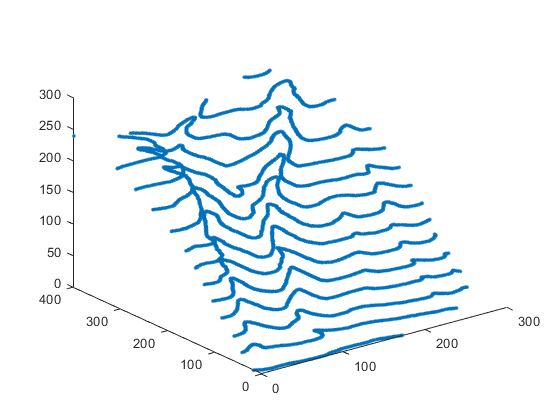

load bluff_data;
x=bluff_data(:,1);
y=bluff_data(:,2);
z=bluff_data(:,3);
% Two ravines on a hillside. Scanned from a
% topographic map of an area in upstate New York.
plot3(x,y,z,'.')

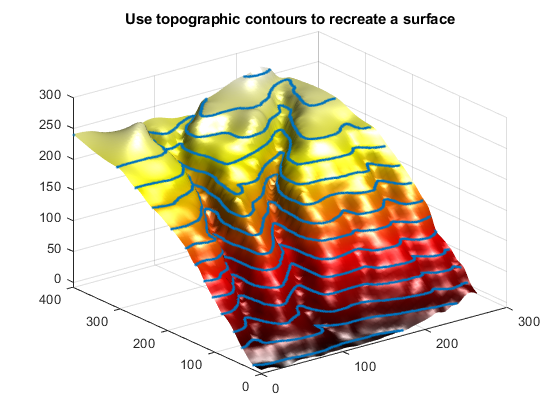

% Turn the scanned point data into a surface
gx=0:4:264;
gy=0:4:400;
smoothness = 0.00001;
g=regularizeNd([x,y] ,z, {gx,gy}, smoothness);
% equivalent calls
% g=regularizeNd([x,y] ,z, {gx,gy}, smoothness, 'linear', 'normal');
% g=regularizeNd([x,y] ,z, {gx,gy}, smoothness, [], []);
% alternative calls
% g=regularizeNd([x,y] ,z, {gx,gy}, smoothness, [], '\');
% g=regularizeNd([x,y] ,z, {gx,gy}, smoothness, 'cubic', 'normal');
% g=regularizeNd([x,y] ,z, {gx,gy}, smoothness, 'cubic', '\');

figure
colormap(hot(256));
surf(gx,gy,g');
camlight right;
lighting phong;
shading interp
line(x,y,z,'marker','.','markersize',4,'linestyle','none');
title 'Use topographic contours to recreate a surface'

## Fitting a trigonometric surface

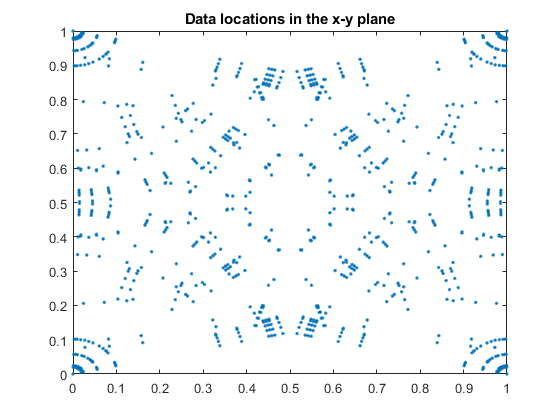

clear

% make the random number sequence repeatable
rng(20170401);

n1 = 15;
n2 = 15;
theta = rand(n1,1)*pi/2;
r = rand(1,n2);

x = cos(theta)*r;
y = sin(theta)*r;
x=x(:);
y=y(:);

x = [[0 0 1 1]';x;x;1-x;1-x];
y = [[0 1 0 1]';y;1-y;y;1-y];
figure
plot(x,y,'.')
title 'Data locations in the x-y plane'

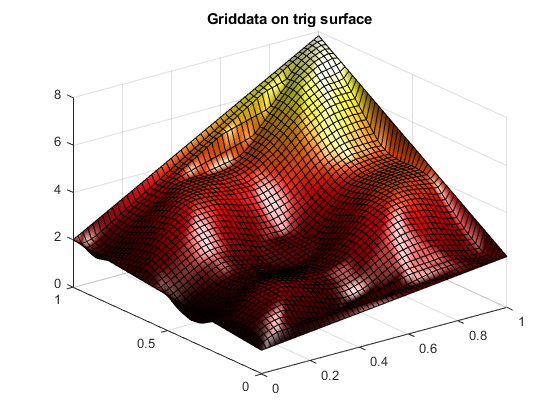

z = sin(4*x+5*y).*cos(7*(x-y))+exp(x+y);

xi = linspace(0,1,51);
[xg,yg]=meshgrid(xi,xi);
zgd = griddata(x,y,z,xg,yg);

figure
surf(xi,xi,zgd)
colormap(hot(256))
camlight right
lighting phong
title 'Griddata on trig surface'

% Note the wing-like artifacts along the edges, due
% to the use of a Delaunay triangulation in griddata.

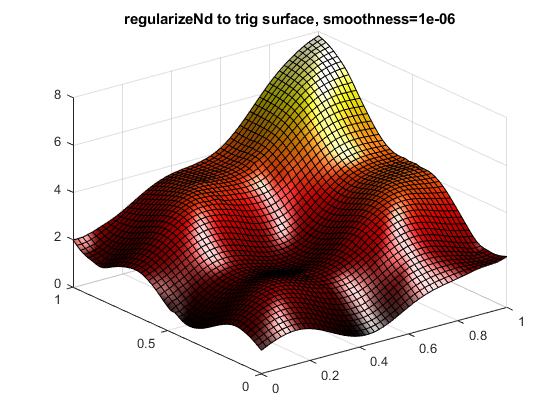

xGrid = {xi,xi};
smoothness = 1e-6;
zGrid = regularizeNd([x,y], z, xGrid, smoothness);

figure
surf(xi,xi,zGrid')
colormap(hot(256))
camlight right
lighting phong
title(sprintf('regularizeNd to trig surface, smoothness=%g', smoothness))

## The trig surface with highly different scalings on the x and y axes

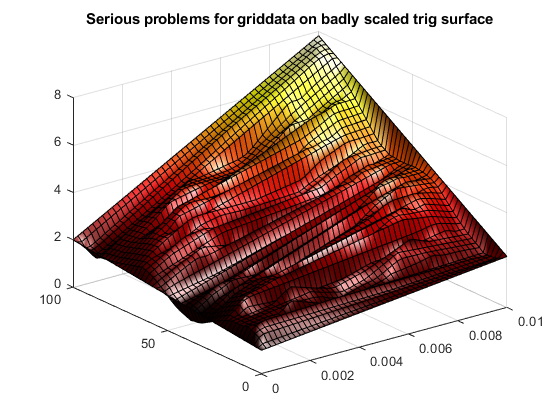

xs = x/100;
xis = xi/100;

ys = y*100;
yis = xi*100;

% griddata has problems with badly scaled data
[xg,yg]=meshgrid(xis,yis);
zgd = griddata(xs,ys,z,xg,yg);

figure
surf(xg,yg,zgd)
colormap(hot(256))
camlight right
lighting phong
title 'Serious problems for griddata on badly scaled trig surface'

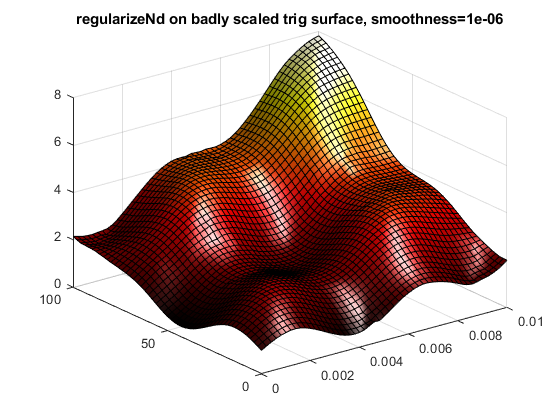


% No need for scaling with regularizeNd
zgrids = regularizeNd([xs,ys],z,{xis,yis}, smoothness);

% plot the result
figure
surf(xis,yis,zgrids)
colormap(hot(256))
camlight right
lighting phong
title(sprintf('regularizeNd on badly scaled trig surface, smoothness=%g', smoothness))

## Fitting the "peaks" surface

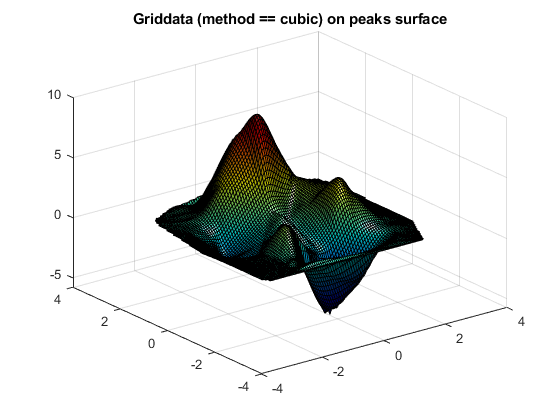

clear

n = 100;
x = (rand(n,1)-.5)*6;
y = (rand(n,1)-.5)*6;

z = peaks(x,y);

xi = linspace(-3,3,101);
smoothness = 0.0001;
zpgf = regularizeNd([x,y],z,{xi,xi}, smoothness, 'cubic');

[xg,yg]=meshgrid(xi,xi);
zpgd = griddata(x,y,z,xg,yg,'cubic');

figure
surf(xi,xi,zpgd)
colormap(jet(256))
camlight right
lighting phong
title 'Griddata (method == cubic) on peaks surface'

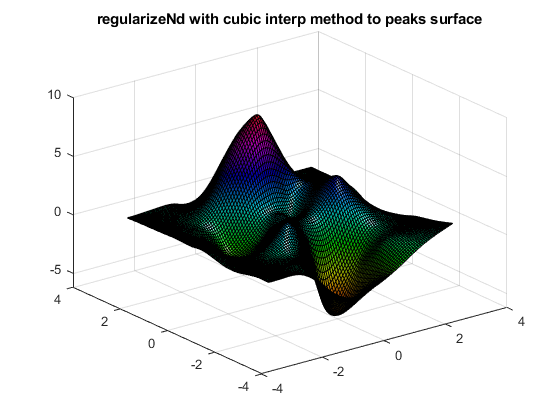


figure
surf(xi,xi,zpgf')
colormap(hsv(256))
camlight right
lighting phong
title('regularizeNd with cubic interp method to peaks surface')

## No need for tiles with regularizeNd

% gridfit had a option called tiles. It was made for handling large
% problems. However, no option like this exists in regularizeNd. The case
% here the is no longer of severe consequence. The problem solves in a few
% seconds. I have solved problems with as many as 3000 grid points (2e6
% unknowns) in each dimension in under a minute. 

n = 100000;
x = rand(n,1);
y = rand(n,1);
z = x+y+sin((x.^2+y.^2)*10);

xnodes = 0:.00125:1;
ynodes = xnodes;
smoothness = 0.001;
tic;
zg = regularizeNd([x,y], z, {xnodes,ynodes}, smoothness);
toc;

Elapsed time is 6.786547 seconds.


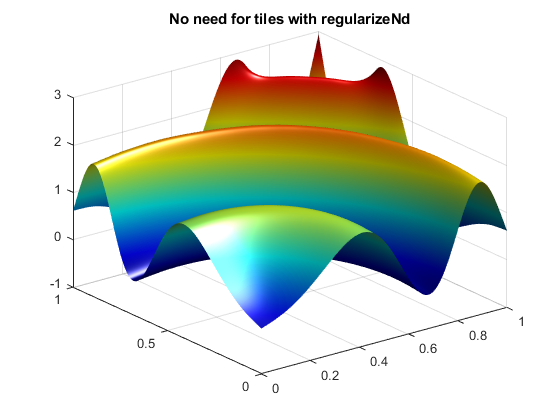


figure;
surf(xnodes, ynodes, zg')
shading interp
colormap(jet(256))
camlight right
lighting phong
title 'No need for tiles with regularizeNd'